k1 = 4.66

k1 = 4.6600

k2 = k1

k2 = 4.6600

m1 = 0.0917

m1 = 0.0917

m2 = 0.0765

m2 = 0.0765


A = [0 1 0 0; -(k1+k2)/m1 0 k2/m1 0; 0 0 0 1;  k2/m2 0 -k2/m2 0];
initCond = [100 0 50 0].';

listPos = 1;
i = 100000

i = 100000

timeStep = 10/i;
timeTraj = (0:timeStep:10-timeStep)

timeTraj =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


traj = zeros(4, i);
presentCond = initCond

presentCond =    100
     0
    50
     0


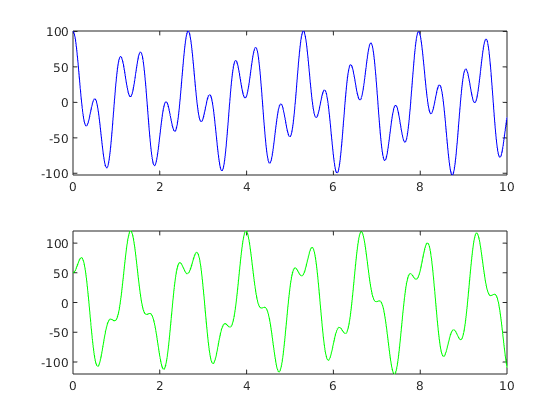

for t = 1:i
    step = (presentCond + A*presentCond.*timeStep);
    traj(:,t) = step;
    presentCond = step;
end
subplot(2, 1, 1);
xlabel("Time in seconds");
ylabel("Position (x1)");
plot(timeTraj, traj(1,:),'b');
hold on

listPos = listPos + 1;
subplot(2, 1, 2);
xlabel("Time in seconds");
ylabel("Position (x2)");
plot(timeTraj, traj(3,:),'g');
listPos = listPos + 1;
hold on

   
period = 2.68
freq = 1/period